# KEVIN JAUKI

%% Environmental Brain Cube - Free Scan Analysis
% This script looks at free scan log data from the cube.
% It reads one run, makes graphs, shows warning counts,
% and prints simple conclusions at the end.
%
% Main things:
% - reads the CSV text file
% - finds the run to use
% - makes midpoint values from min/max data
% - plots temperature, humidity, pressure, power, light, motion
% - shows summary tables
% - prints simple conclusions
%

clear; clc; close all;

%% settings
fileName = "ebc_free_log.csv";   
runChoice = "8";            % "latest" or a run number like "2" (make sure run number is accurate and quoted"")

tempWarnC = 50;
humWarnHigh = 85;

%% check file
if ~isfile(fileName)
    error("File not found: " + fileName);
end

%% read file as lines
txt = fileread(fileName);
lines = splitlines(string(txt));
lines = strtrim(lines);
lines = lines(lines ~= "");

%% keep only real data lines
dataLines = strings(0,1);

for i = 1:length(lines)
    lineNow = lines(i);

    if startsWith(lineNow, "RUN") && ~startsWith(lineNow, "=== RUN")
        parts = split(lineNow, ",");
        if numel(parts) >= 30
            dataLines(end+1,1) = lineNow; %#ok<SAGROW>
        end
    end
end

if isempty(dataLines)
    error("No valid RUN data rows found.");
end

%% make arrays
n = length(dataLines);

runNum = nan(n,1);
timeSec = nan(n,1);

lightMin = nan(n,1);
lightMax = nan(n,1);
lightState = strings(n,1);

bmeTempMin = nan(n,1);
bmeTempMax = nan(n,1);

bmeHumMin = nan(n,1);
bmeHumMax = nan(n,1);

bmePresMin = nan(n,1);
bmePresMax = nan(n,1);

dsTempMin = nan(n,1);
dsTempMax = nan(n,1);

battMin = nan(n,1);
battMax = nan(n,1);

solarMin = nan(n,1);
solarMax = nan(n,1);

axMin = nan(n,1);
axMax = nan(n,1);

ayMin = nan(n,1);
ayMax = nan(n,1);

azMin = nan(n,1);
azMax = nan(n,1);

gxMin = nan(n,1);
gxMax = nan(n,1);

gyMin = nan(n,1);
gyMax = nan(n,1);

gzMin = nan(n,1);
gzMax = nan(n,1);

%% pull values from each row
for i = 1:n
    row = split(dataLines(i), ",");
    row = strtrim(row);

    runNum(i) = sscanf(row(1), "RUN%d");
    timeSec(i) = makeNum(row(3));

    lightMin(i) = makeNum(row(4));
    lightMax(i) = makeNum(row(5));
    lightState(i) = row(6);

    bmeTempMin(i) = makeNum(row(7));
    bmeTempMax(i) = makeNum(row(8));

    bmeHumMin(i) = makeNum(row(9));
    bmeHumMax(i) = makeNum(row(10));

    bmePresMin(i) = makeNum(row(11));
    bmePresMax(i) = makeNum(row(12));

    dsTempMin(i) = makeNum(row(13));
    dsTempMax(i) = makeNum(row(14));

    battMin(i) = makeNum(row(15));
    battMax(i) = makeNum(row(16));

    solarMin(i) = makeNum(row(17));
    solarMax(i) = makeNum(row(18));

    axMin(i) = makeNum(row(19));
    axMax(i) = makeNum(row(20));

    ayMin(i) = makeNum(row(21));
    ayMax(i) = makeNum(row(22));

    azMin(i) = makeNum(row(23));
    azMax(i) = makeNum(row(24));

    gxMin(i) = makeNum(row(25));
    gxMax(i) = makeNum(row(26));

    gyMin(i) = makeNum(row(27));
    gyMax(i) = makeNum(row(28));

    gzMin(i) = makeNum(row(29));
    gzMax(i) = makeNum(row(30));
end

%% make table
T = table(runNum,timeSec,...
    lightMin,lightMax,lightState,...
    bmeTempMin,bmeTempMax,...
    bmeHumMin,bmeHumMax,...
    bmePresMin,bmePresMax,...
    dsTempMin,dsTempMax,...
    battMin,battMax,...
    solarMin,solarMax,...
    axMin,axMax,...
    ayMin,ayMax,...
    azMin,azMax,...
    gxMin,gxMax,...
    gyMin,gyMax,...
    gzMin,gzMax);

%% choose run
allRuns = unique(T.runNum);

if runChoice == "latest"
    runToUse = max(allRuns);
else
    runToUse = double(runChoice);
end

D = T(T.runNum == runToUse, :);
D = sortrows(D, "timeSec");

if isempty(D)
    error("Selected run not found.");
end

fprintf("Using RUN%d\n", runToUse);

Using RUN8


fprintf("Intervals logged: %d\n", height(D));

Intervals logged: 1381


fprintf("Run duration: %.2f s\n", max(D.timeSec));

Run duration: 2799.76 s


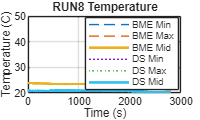


%% make midpoint values
D.bmeTempMid = (D.bmeTempMin + D.bmeTempMax) / 2;
D.dsTempMid  = (D.dsTempMin  + D.dsTempMax)  / 2;
D.bmeHumMid  = (D.bmeHumMin  + D.bmeHumMax)  / 2;
D.bmePresMid = (D.bmePresMin + D.bmePresMax) / 2;

D.battMid  = (D.battMin + D.battMax) / 2;
D.solarMid = (D.solarMin + D.solarMax) / 2;
D.lightMid = (D.lightMin + D.lightMax) / 2;

D.axMid = (D.axMin + D.axMax) / 2;
D.ayMid = (D.ayMin + D.ayMax) / 2;
D.azMid = (D.azMin + D.azMax) / 2;

D.gxMid = (D.gxMin + D.gxMax) / 2;
D.gyMid = (D.gyMin + D.gyMax) / 2;
D.gzMid = (D.gzMin + D.gzMax) / 2;

%% temperature graph
figure
plot(D.timeSec, D.bmeTempMin, '--', 'LineWidth', 1)
hold on
plot(D.timeSec, D.bmeTempMax, '--', 'LineWidth', 1)
plot(D.timeSec, D.bmeTempMid, 'LineWidth', 2)

plot(D.timeSec, D.dsTempMin, ':', 'LineWidth', 1)
plot(D.timeSec, D.dsTempMax, ':', 'LineWidth', 1)
plot(D.timeSec, D.dsTempMid, 'LineWidth', 2)

yline(tempWarnC, '--', 'Temp warning')
grid on
xlabel('Time (s)')
ylabel('Temperature (C)')
title("RUN" + runToUse + " Temperature")
legend('BME Min','BME Max','BME Mid','DS Min','DS Max','DS Mid','Location','best')

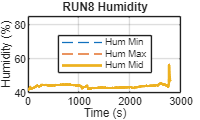


%% humidity graph
figure
plot(D.timeSec, D.bmeHumMin, '--', 'LineWidth', 1)
hold on
plot(D.timeSec, D.bmeHumMax, '--', 'LineWidth', 1)
plot(D.timeSec, D.bmeHumMid, 'LineWidth', 2)
yline(humWarnHigh, '--', 'Humidity warning')
grid on
xlabel('Time (s)')
ylabel('Humidity (%)')
title("RUN" + runToUse + " Humidity")
legend('Hum Min','Hum Max','Hum Mid','Location','best')

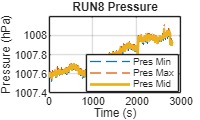


%% pressure graph
figure
plot(D.timeSec, D.bmePresMin, '--', 'LineWidth', 1)
hold on
plot(D.timeSec, D.bmePresMax, '--', 'LineWidth', 1)
plot(D.timeSec, D.bmePresMid, 'LineWidth', 2)
grid on
xlabel('Time (s)')
ylabel('Pressure (hPa)')
title("RUN" + runToUse + " Pressure")
legend('Pres Min','Pres Max','Pres Mid','Location','best')

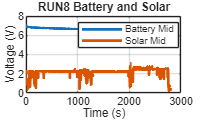


%% battery and solar graph
figure
plot(D.timeSec, D.battMid, 'LineWidth', 2)
hold on
plot(D.timeSec, D.solarMid, 'LineWidth', 2)
grid on
xlabel('Time (s)')
ylabel('Voltage (V)')
title("RUN" + runToUse + " Battery and Solar")
legend('Battery Mid','Solar Mid','Location','best')

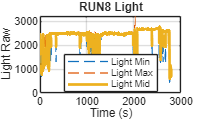


%% light graph
figure
plot(D.timeSec, D.lightMin, '--', 'LineWidth', 1)
hold on
plot(D.timeSec, D.lightMax, '--', 'LineWidth', 1)
plot(D.timeSec, D.lightMid, 'LineWidth', 2)
grid on
xlabel('Time (s)')
ylabel('Light Raw')
title("RUN" + runToUse + " Light")
legend('Light Min','Light Max','Light Mid','Location','best')

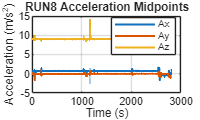


%% accel graph
figure
plot(D.timeSec, D.axMid, 'LineWidth', 1.5)
hold on
plot(D.timeSec, D.ayMid, 'LineWidth', 1.5)
plot(D.timeSec, D.azMid, 'LineWidth', 1.5)
grid on
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')
title("RUN" + runToUse + " Acceleration Midpoints")
legend('Ax','Ay','Az','Location','best')

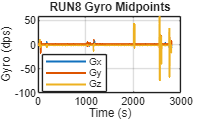


%% gyro graph
figure
plot(D.timeSec, D.gxMid, 'LineWidth', 1.5)
hold on
plot(D.timeSec, D.gyMid, 'LineWidth', 1.5)
plot(D.timeSec, D.gzMid, 'LineWidth', 1.5)
grid on
xlabel('Time (s)')
ylabel('Gyro (dps)')
title("RUN" + runToUse + " Gyro Midpoints")
legend('Gx','Gy','Gz','Location','best')


%% summary table
Parameter = [
    "BME Temp (C)"
    "DS Temp (C)"
    "Humidity (%)"
    "Pressure (hPa)"
    "Battery (V)"
    "Solar (V)"
    "Light (raw)"
    ];

OverallMin = [
    min(D.bmeTempMin,[],'omitnan')
    min(D.dsTempMin,[],'omitnan')
    min(D.bmeHumMin,[],'omitnan')
    min(D.bmePresMin,[],'omitnan')
    min(D.battMin,[],'omitnan')
    min(D.solarMin,[],'omitnan')
    min(D.lightMin,[],'omitnan')
    ];

OverallMax = [
    max(D.bmeTempMax,[],'omitnan')
    max(D.dsTempMax,[],'omitnan')
    max(D.bmeHumMax,[],'omitnan')
    max(D.bmePresMax,[],'omitnan')
    max(D.battMax,[],'omitnan')
    max(D.solarMax,[],'omitnan')
    max(D.lightMax,[],'omitnan')
    ];

MidAverage = [
    mean(D.bmeTempMid,'omitnan')
    mean(D.dsTempMid,'omitnan')
    mean(D.bmeHumMid,'omitnan')
    mean(D.bmePresMid,'omitnan')
    mean(D.battMid,'omitnan')
    mean(D.solarMid,'omitnan')
    mean(D.lightMid,'omitnan')
    ];

Summary = table(Parameter, OverallMin, OverallMax, MidAverage);
Summary

Summary = 7×4 table
       Parameter        OverallMin    OverallMax    MidAverage
    ________________    __________    __________    __________

    "BME Temp (C)"          21.3         23.91        22.906  
    "DS Temp (C)"          20.25            21        20.758  
    "Humidity (%)"         41.98         56.93        43.945  
    "Pressure (hPa)"      1007.5        1008.1        1007.8  
    "Battery (V)"           5.84          7.13         6.582  
    "Solar (V)"             0.04          3.73        2.1664  
    "Light (raw)"            464          3227        2346.8  



%% warning table
tempWarnCount = sum((D.bmeTempMax > tempWarnC) | (D.dsTempMax > tempWarnC));
humWarnCount = sum(D.bmeHumMax > humWarnHigh);

WarningSummary = table( ...
    runToUse, ...
    height(D), ...
    tempWarnCount, ...
    humWarnCount, ...
    100*tempWarnCount/height(D), ...
    100*humWarnCount/height(D), ...
    'VariableNames', ...
    {'Run','Intervals','TempWarningCount','HumidityWarningCount','TempWarningPercent','HumidityWarningPercent'});

WarningSummary

WarningSummary = 1×6 table
    Run    Intervals    TempWarningCount    HumidityWarningCount    TempWarningPercent    HumidityWarningPercent
    ___    _________    ________________    ____________________    __________________    ______________________

     8       1381              0                     0                      0                       0           



%% light summary
lightCat = categorical(D.lightState);
cats = categories(lightCat);
counts = countcats(lightCat);

LightSummary = table(cats, counts, 100*counts/sum(counts), ...
    'VariableNames', {'LightState','Count','Percent'});

LightSummary

LightSummary = 2×3 table
    LightState    Count    Percent
    __________    _____    _______

    {'DARK'  }      34      2.462 
    {'NORMAL'}    1347     97.538 



%% simple conclusions
fprintf('\n================ SIMPLE CONCLUSIONS ================\n');


================ SIMPLE CONCLUSIONS ================



fprintf('Run analyzed: RUN%d\n', runToUse);

Run analyzed: RUN8


fprintf('Total run time analyzed: %.2f s\n', max(D.timeSec));

Total run time analyzed: 2799.76 s



fprintf('\nTemperature:\n');


Temperature:


fprintf('- Average BME temperature midpoint: %.2f C\n', mean(D.bmeTempMid,'omitnan'));

- Average BME temperature midpoint: 22.91 C


fprintf('- Average DS temperature midpoint: %.2f C\n', mean(D.dsTempMid,'omitnan'));

- Average DS temperature midpoint: 20.76 C


fprintf('- Highest temperature observed: %.2f C\n', ...
    max([max(D.bmeTempMax,[],'omitnan'), max(D.dsTempMax,[],'omitnan')]));

- Highest temperature observed: 23.91 C



fprintf('\nHumidity:\n');


Humidity:


fprintf('- Average humidity midpoint: %.2f %%\n', mean(D.bmeHumMid,'omitnan'));

- Average humidity midpoint: 43.95 %


fprintf('- Highest humidity observed: %.2f %%\n', max(D.bmeHumMax,[],'omitnan'));

- Highest humidity observed: 56.93 %



fprintf('\nPressure:\n');


Pressure:


fprintf('- Average pressure midpoint: %.2f hPa\n', mean(D.bmePresMid,'omitnan'));

- Average pressure midpoint: 1007.78 hPa



fprintf('\nPower:\n');


Power:


fprintf('- Average battery midpoint: %.2f V\n', mean(D.battMid,'omitnan'));

- Average battery midpoint: 6.58 V


fprintf('- Average solar midpoint: %.2f V\n', mean(D.solarMid,'omitnan'));

- Average solar midpoint: 2.17 V



fprintf('\nWarnings:\n');


Warnings:


if tempWarnCount == 0
    fprintf('- No temperature warning intervals occurred.\n');
else
    fprintf('- Temperature warnings occurred in %d intervals.\n', tempWarnCount);
end

- No temperature warning intervals occurred.



if humWarnCount == 0
    fprintf('- No humidity warning intervals occurred.\n');
else
    fprintf('- Humidity warnings occurred in %d intervals.\n', humWarnCount);
end

- No humidity warning intervals occurred.



if ~isempty(cats)
    [~, idx] = max(counts);
    fprintf('\nLight:\n');
    fprintf('- Most common light state was %s.\n', string(cats(idx)));
end


Light:


- Most common light state was NORMAL.



accSpread = mean([ ...
    max(D.axMax,[],'omitnan') - min(D.axMin,[],'omitnan'), ...
    max(D.ayMax,[],'omitnan') - min(D.ayMin,[],'omitnan'), ...
    max(D.azMax,[],'omitnan') - min(D.azMin,[],'omitnan')], 'omitnan');

gyroSpread = mean([ ...
    max(D.gxMax,[],'omitnan') - min(D.gxMin,[],'omitnan'), ...
    max(D.gyMax,[],'omitnan') - min(D.gyMin,[],'omitnan'), ...
    max(D.gzMax,[],'omitnan') - min(D.gzMin,[],'omitnan')], 'omitnan');

fprintf('\nMotion:\n');


Motion:


if accSpread < 0.05 && gyroSpread < 10
    fprintf('- Motion appears low and stable.\n');
elseif accSpread < 0.3 && gyroSpread < 50
    fprintf('- Motion appears moderate.\n');
else
    fprintf('- Motion appears strong or highly variable.\n');
end

- Motion appears strong or highly variable.



function x = makeNum(s)
    s = strtrim(string(s));

    if s == "NA" || s == ""
        x = NaN;
    else
        x = str2double(s);
    end
end